# Solutions to Exercises on Polynomial Interpolation (26.11.2024)

Course: Data Science for Engineers II

Author: Dimitar Ninevski

Date: 09.12.2024

## Prepare workspace

close all;
clear;

## Question 1

### Part a.

Let's load the dataset first.

load cantileverWithSupportMeasData.mat;

I will convert x and y to columns just for comfort. Mostly because I am lazy to change the formulas I already have in the presentation, and they only work with column vectors.

x = x';
y = y';

The next line of code needs to stay commented until you read everything in part c. Afterwards, you can see the difference between the two options.

% Option 1: Simply divide by some number.
% x = x/1000;
% Option 2: Use the function normalize
% x = normalize(x, 'range', [-1 1]);

Now let's visualize it

figure
plot(x, y, '.', 'MarkerSize', 12);
grid on;
xlabel('x');
ylabel('y');

### Part b. 

Polynomial approximation would be more suited here, since even though the data has 85 points, it seems to have the shape of a much simpler polynomial. The data has two stationary points (points where the first derivative is zero) and one point of inflexion. Thus, a polynomial of degree at least 4 should do the job.

Additionally, the data is "obviously" noisy, and if we don't want to model this noise, approximation is better.

### Part c. 

I choose degrees 4, 7 and 10. Anything higher wouldn't make sense in this case, although it doesn't hurt to try.

deg1 = 4;
deg2 = 7;
deg3 = 10;

First we define the full Vandermonde matrix and then take the necessary columns from it.

fullV = vander(x);
V1 = fullV(:, end-deg1:end);
V2 = fullV(:, end-deg2:end);
V3 = fullV(:, end-deg3:end);

Now we can compute the coefficients of the approximating polynomials.

alpha1 = pinv(V1)*y;
alpha2 = pinv(V2)*y;
alpha3 = pinv(V3)*y;

Finally, we need to define x values for plotting and compute the polynomials for those x values in order to plot them.

xMin = min(x);
xMax = max(x);
nrPts = 400;
xPlot = linspace(xMin, xMax, nrPts);
%
yPlot1 = polyval(alpha1, xPlot);
yPlot2 = polyval(alpha2, xPlot);
yPlot3 = polyval(alpha3, xPlot);

Let's add these to the plot above.

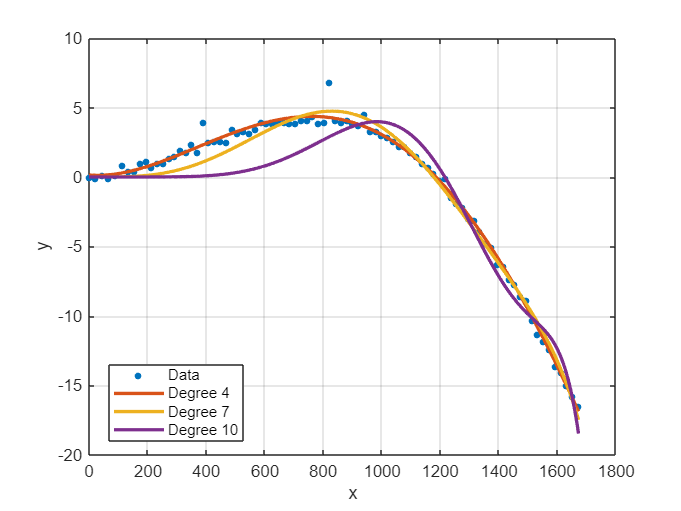

hold on;
plot(xPlot, yPlot1,'LineWidth', 2)
plot(xPlot, yPlot2, 'LineWidth', 2)
plot(xPlot, yPlot3, 'LineWidth', 2)
legend('Data', ['Degree ', num2str(deg1)], ...
    ['Degree ', num2str(deg2)], ['Degree ', num2str(deg3)],...
    'Location', 'Best');

The degree 4 polynomial seems to work fine enough, but the degree 7 and 10 polynomials seem to be getting worse with the increase of degree. This should NOT be the case.

The problem here are the relatively high values of x$x$. When we compute the Vandermonde matrix, we take values as high as $x^{10}$. This means, we have to deal with numbers of order $10^{30}$, which is obviously too much for MATLAB to handle. 

In order to fix this, we can scale the values of x to some smaller values, to make it easier for MATLAB to compute them. Once we have fit the polynomials to the smaller values, we can later scale them back if needed to the original values.

So, up there I will add some lines of code (lines 6-9), which will initially be commented out, so you can see the "bad" way, before you apply the fix. If you uncomment that line of code, it should work fine.

Note that these problems don't appear if you use the MATLAB function polyfit, but the function gives you a warning. The function does something similar in the background when it deals with high values like this.

## Question 2

First, let's load and visualize the data.

load Data2D.mat;

The variable is called D. Notice, that the data has only the $z$ values, and the$x$ and$y$ values need to be defined by us.

It's a 2D data, so I will use imagesc to visualize it using colors.

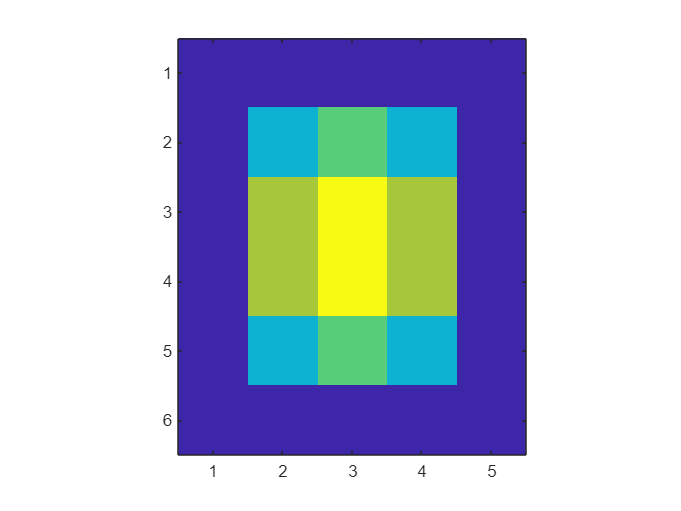

figure
imagesc(D);
axis image;

I add the axis image, so the scaling of the "pixels" is the same as in an actual image.

### Part a.

Since there are 6 points in the vertical$y$ direction, we need a polynomial of degree 5 in that direction. Similarly, we need a polynomial of degree 4 in the$x$ direction.

### Part b.

First, we need to define the degrees and compute the basis function matrices in the$x$ and$y$ direction.

[nrPtsY, nrPtsX] = size(D);
degX = nrPtsX - 1;
degY = nrPtsY - 1;

Now we need to define some$x$ and$y$ vectors.

x2 = linspace(-1, 1, nrPtsX);
y2 = linspace(-1, 1, nrPtsY);

Next we define the basis function matrices in both directions.

Bx = vander(x2);
By = vander(y2);

Finally, perform polynomial interpolation.

coeffs = pinv(By)*D*pinv(Bx');

Note: in the presentation, the formula used it $B_x^+ D(B_y^T)^+ $.

This is due to me mixing up the$x$ and$y$ directions. Both options are fine and correct, we just need to be careful to stay consistent. 

We could turn the order of the matrices around in the code here, and we would just need to transpose the matrix D in order to make it work. coeffs = pinv(Bx)*D'*pinv(By');

### Part c.

Now we need to visualize the surface. In order to do that, we need to define a finer grid of$x$ and$y$ values. Because I want the final surface to have the same ration of height:width as the original data, I will increase the number of points by scaling with a factor.

factor = 20;
nrPtsXPlot = factor*nrPtsX;
nrPtsYPlot = factor*nrPtsY;
x2Plot = linspace(-1, 1, nrPtsXPlot);
y2Plot = linspace(-1, 1, nrPtsYPlot);

Now that the plotting$x$ and$y$ values are defined, we need to compute the interpolating bases for the computation (this was done by polyval in the 1D case).

fullVx = vander(x2Plot);
fullVy = vander(y2Plot);
BxPlot = fullVx(:, end-degX:end);
ByPlot = fullVy(:, end-degY:end);

Now we can compute the interpolating surface.

polySurf = ByPlot*coeffs*BxPlot';

Finally, we can plot the interpolated surface

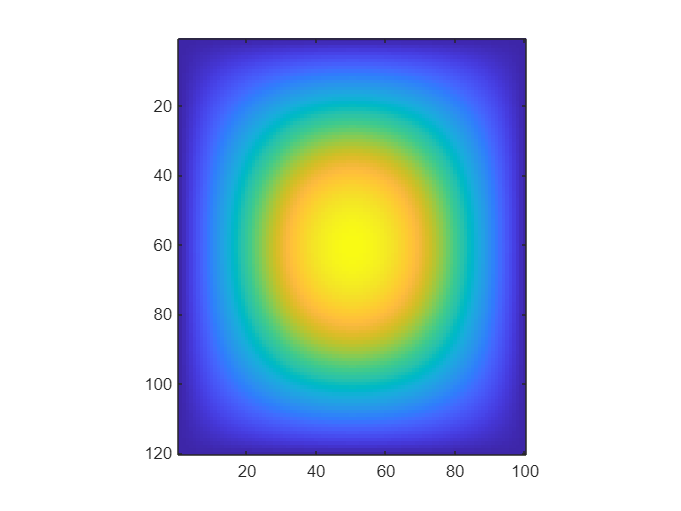

figure
imagesc(polySurf);
axis image;

## Extra stuff

Maybe plotting the surfaces as actual surfaces could help with understanding and visualization. So, let's do that. We will use MATLABs function surf.

It requires a special grid of$x$ and$y$ values. The code for it is as follows:

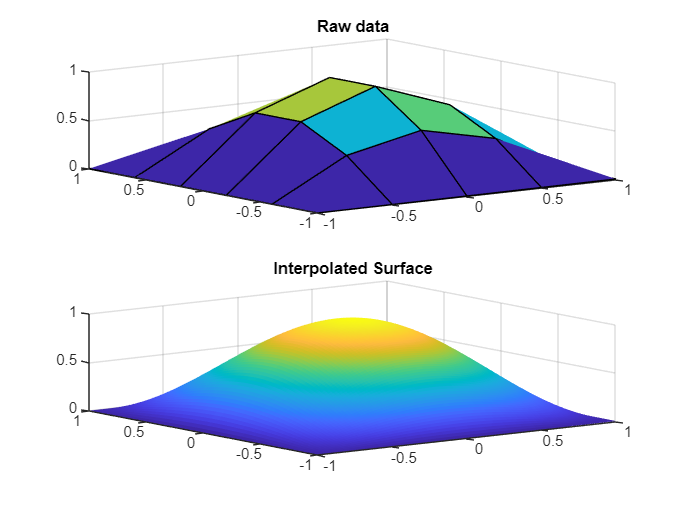

figure
[xSurf, ySurf] = meshgrid(x2, y2);
subplot(2,1,1)
surf(xSurf, ySurf, D);
title('Raw data')
[x2Surf, y2Surf] = meshgrid(x2Plot, y2Plot);
subplot(2,1,2)
surf(x2Surf, y2Surf, polySurf, 'EdgeColor', 'none');
title('Interpolated Surface')